#### Creating the Unique Matches

N = 8;
number_unique_sets_of_pairs = factorial(N)/power(2,N/2)/factorial(N/2)

number_unique_sets_of_pairs = 105


unique_sets_of_matches = cell(1,number_unique_sets_of_pairs);

for index = 1:number_unique_sets_of_pairs
    unique_sets_of_matches{index} = nan(2,N/2);
end

possible_pairings = nchoosek(1:N,2);

possible_pair_sets = nchoosek(1:size(possible_pairings,1),N/2);

counter = 0;
for pair_set_index = 1:size(possible_pair_sets,1)
    possible_pair_set_values = possible_pairings(possible_pair_sets(pair_set_index,:),:);
    possible_pair_set_values = possible_pair_set_values(:);
    if length(unique(possible_pair_set_values)) == N
        counter = counter + 1;
        unique_sets_of_matches{counter} = possible_pairings(possible_pair_sets(pair_set_index,:),:)';
    end

end

if counter ~= number_unique_sets_of_pairs
    warning('Counter ~= Number of Unique Sets of Pairs')
end

unique_sets_of_matches

unique_sets_of_matches = 1×105 cell array
    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 double}    {2×4 doubl

#### Generating Sorted P Values and Looking at Profitability of Each Matching Scheme with P2P Gambling

M = 1;
x = 1;

num_trials = 100;
unique_set_of_pairs_profits = zeros(num_trials,number_unique_sets_of_pairs);
for trial_number = 1:num_trials
    p_values = sort(rand(1,N));
    for unique_set_of_pairs_index = 1:number_unique_sets_of_pairs
        unique_set_of_matches = unique_sets_of_matches{unique_set_of_pairs_index};
        for pair_index = 1:(N/2)
            p1 = p_values(unique_set_of_matches(1,pair_index));
            p2 = p_values(unique_set_of_matches(2,pair_index));
            peer_bet = peer_to_peer(p1,p2,M,x);
            unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) = unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) + peer_bet.profit;
        end
    end
end

sum(unique_set_of_pairs_profits)

ans =    20.3041   29.3445   29.1940   32.7495   41.8188   41.5458   32.8986   50.5799   50.4574   42.1437   50.7557   50.6621   42.0236   50.7861   50.8150   28.8609   37.9013   37.7508   41.2926   50.3619   50.0890   41.5053   59.1865   59.0641   51.0987   59.7107   59.6172   51.4033   60.1657   60.1947   28.6026   37.6430   37.4925   52.8023   62.0474   61.9273   52.8658   70.8720   70.9024   62.4593   71.2204   71.4555   62.7638   71.6754   71.8801   40.7798   49.8491   49.5761   52.5478   61.7929


[~,best_strategy_indeces] = max(unique_set_of_pairs_profits,[],2);
best_strategy_indeces = unique(best_strategy_indeces)

best_strategy_indeces =     53
    54
    57
    59
    60
    68
    71
    75
    83
    86


unique_sets_of_matches{best_strategy_indeces}

ans =      1     2     3     4
     5     6     7     8


ans =      1     2     3     4
     5     6     8     7


ans =      1     2     3     4
     5     7     8     6


ans =      1     2     3     4
     5     8     6     7


ans =      1     2     3     4
     5     8     7     6


ans =      1     2     3     4
     6     5     7     8


ans =      1     2     3     4
     6     7     5     8


ans =      1     2     3     4
     6     8     7     5


ans =      1     2     3     4
     7     5     6     8


ans =      1     2     3     4
     7     6     5     8


ans =      1     2     3     4
     7     8     5     6


ans =      1     2     3     4
     7     8     6     5


ans =      1     2     3     4
     8     5     6     7


ans =      1     2     3     4
     8     5     7     6


ans =      1     2     3     4
     8     6     5     7


ans =      1     2     3     4
     8     6     7     5


ans =      1     2     3     4
     8     7     5     6


ans =      1     2     3     4
     8     7     6     5


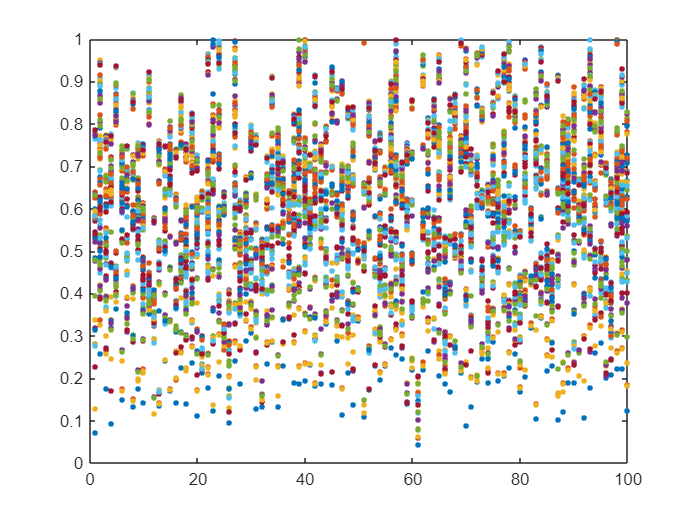


plot(unique_set_of_pairs_profits,'LineStyle','none','Marker','.','MarkerSize',10)
% Box and Whiskers
unique_set_of_pairs_profits = sum(unique_set_of_pairs_profits)/num_trials;

ylim([0 1])